Problem 4.48

Consider the DC motor speed-control system shown in Fig. 4.60 with proportional control. 

(a) Add feedforward control to eliminate the steady-state tracking error for a step reference input. 

(b) Also add feedforward control to eliminate the effect of a constant output disturbance signal, w, on the output of the system.

**a.)**

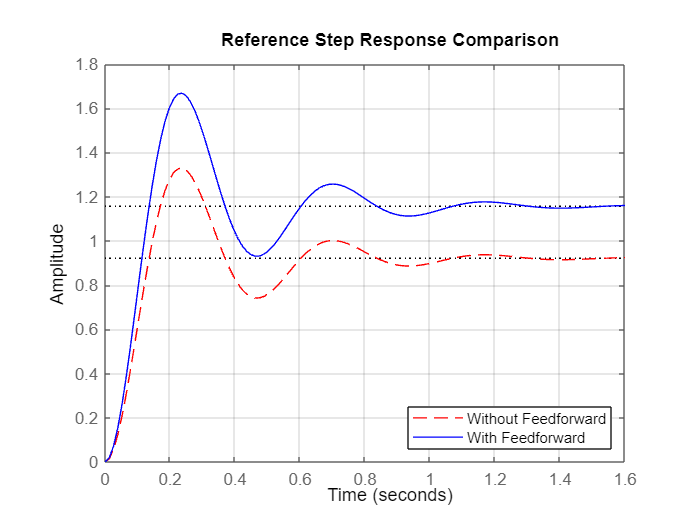


G = tf(59.292, [1, 6.978, 15.123]);

Kp = 3;

K_ff = 15.123 / 59.292;        

sys_no_ff = (Kp * G) / (1 + Kp * G);         
sys_ff = (1+K_ff) * sys_no_ff;

figure;
step(sys_no_ff, 'r--', sys_ff, 'b-');
legend('Without Feedforward', 'With Feedforward', 'Location', 'Southeast');
title('Reference Step Response Comparison');
grid on;

**b.)**

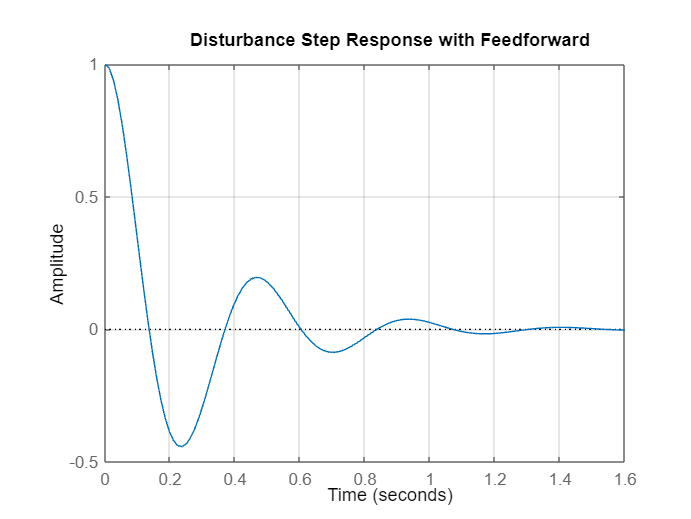


K_fw = K_ff / Kp;
sys_dist = (1 - Kp * K_fw * G) / (1 + Kp * G);

figure;
step(sys_dist);
title('Disturbance Step Response with Feedforward');
grid on;


disp('Steady-state gain of disturbance response:');

Steady-state gain of disturbance response:


     9.2040e-018

